# **JPEG encoder**

## 1- Read the image 

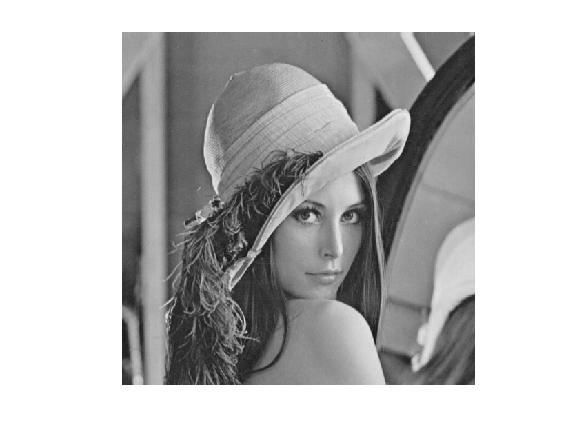

%Read the image 
image = rgb2gray(imread('girl.jpg'));    %convert it to grayscale
imshow(image)

image = im2double(image);    %convert it to double to be able to perform DCT

## and divide it into 8*8 blocks

[r,c] = size(image);
dct_image = zeros(r,c);    %this will store the DCT of the whole image

%Divide the image into 8*8 blocks
for i = 1:8:r
    for j = 1:8:c
        
        % current 8*8 block from the image
        current_block(1:8, 1:8) = image(i:i+7, j:j+7);

## 2- Perform DCT on each block

        %DCT of the current 8*8 block is computed then stored in dct_image
        dct_image(i:i+7, j:j+7) = my_dct(current_block);

## 3- Quantization step 

####      a) Table 1

        %quantization function taked the 8*8 block dct of an image, and the
        % quantization table choice, and returns the quantized image
        quantized_image_1(i:i+7, j:j+7) = quantization(dct_image(i:i+7, j:j+7), 1);

####      b) Table 2

        quantized_image_2(i:i+7, j:j+7) = quantization(dct_image(i:i+7, j:j+7), 2);

####      c) Table 3

        quantized_image_3(i:i+7, j:j+7) = quantization(dct_image(i:i+7, j:j+7), 3);
    end
end

## 4- Transform each block from a 2-D matrix to a 1-D vector using Zig-Zag scan method

zizag_arr1 = zigzag(quantized_image_1);
zizag_arr2 = zigzag(quantized_image_2);
zizag_arr3 = zigzag(quantized_image_3);

## 5- Perform Run-Length Encoding

run_len1 = run_length_coding(zizag_arr1);
run_len2 = run_length_coding(zizag_arr2);
run_len3 = run_length_coding(zizag_arr3);

## 6- Huffman Encoding

[code1, dict1] = huffman_encode(run_len1);
[code2, dict2] = huffman_encode(run_len2);
[code3, dict3] = huffman_encode(run_len3);

# **JPEG Decoder**

## 1- Huffman Decoding

vector1 = huffmandeco(code1, dict1);
vector2 = huffmandeco(code2, dict2);
vector3 = huffmandeco(code3, dict3);

## 2- Perform Run-Length Decoding

run_length_dec1 = run_length_decoding(vector1);
run_length_dec2 = run_length_decoding(vector2);
run_length_dec3 = run_length_decoding(vector3);

## 3- Transform the 1-D vector into groups of 8x8 matrices

inv_zigzag1= inverse_zigzag(run_length_dec1);
inv_zigzag2= inverse_zigzag(run_length_dec2);
inv_zigzag3= inverse_zigzag(run_length_dec3);

## 4- Inverse Quantization Step

for i = 1:8:r
    for j = 1:8:c
        
        %table 1
        inv_quantized_image_1(i:i+7, j:j+7) = inverse_quantization(inv_zigzag1(i:i+7, j:j+7), 1);
        %table 2
        inv_quantized_image_2(i:i+7, j:j+7) = inverse_quantization(inv_zigzag2(i:i+7, j:j+7), 2);
        %table 3
        inv_quantized_image_3(i:i+7, j:j+7) = inverse_quantization(inv_zigzag3(i:i+7, j:j+7), 3);


## 5- Perform IDCT on each 8x8 pixel group

        %IDCT
        idct_image1(i:i+7, j:j+7) = my_idct(inv_quantized_image_1(i:i+7, j:j+7));
        idct_image2(i:i+7, j:j+7) = my_idct(inv_quantized_image_2(i:i+7, j:j+7));
        idct_image3(i:i+7, j:j+7) = my_idct(inv_quantized_image_3(i:i+7, j:j+7));

    end
end

## 6- Combine the 8x8 pixel groups into a single image

image1 = idct_image1;
image2 = idct_image2;
image3 = idct_image3;

## 7- Save the image back to a file

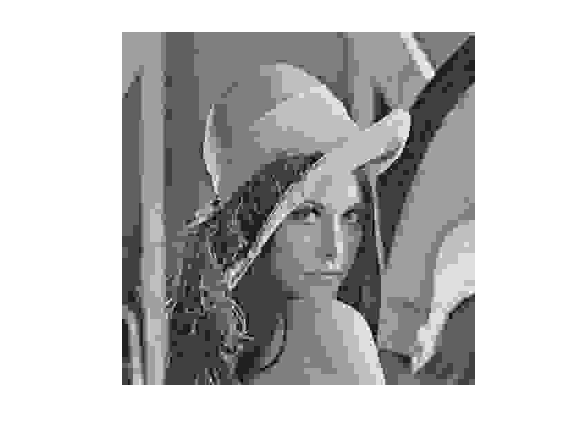

% first image (using the first quantization table)
imshow(im2uint8(idct_image1))
imsave();

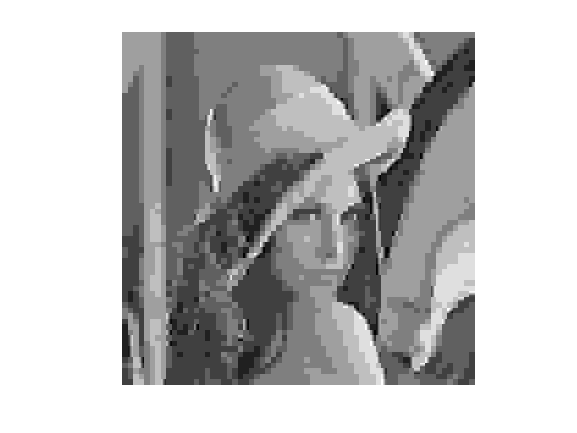

% second image (using the second quantization table)
imshow(im2uint8(idct_image2));
imsave();

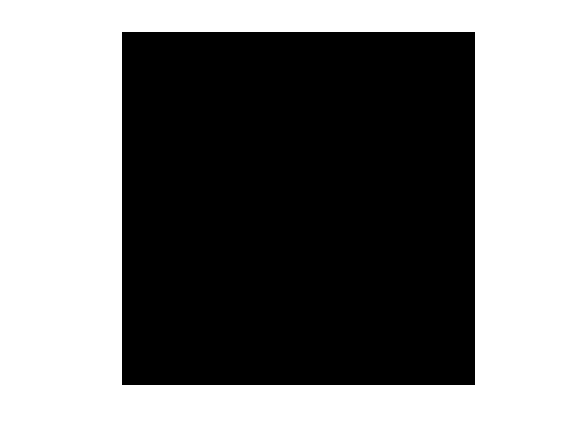

% third image (using the third quantization table)
imshow(im2uint8(idct_image3));
imsave();

The image is completely lost!

## 8- Comparison between the original image and the compressed image 

- For Quantization table 1: Some details disappeared. This happens as a result of increasing the values of the AC components in the quantization table, which increases the compression at the expense of removing some details, therefore decreasing the quality.

- For Quantization table 2: Just like 1, but more details disappeared and the quality decreased.

- For Quantization table 3: In this case, the quantization table had very large values. As a result, we lost our image and cannot get it back. 

## 9- Compression Ratio 

% Compression ratio = bits before compression / bits after compression
% Bits before compression = rows * columns * 8
% Bits after compression = length of the code vector produced by huffman

bits_before = r * c * 8;
bits_after1 = length(code1);
bits_after2 = length(code2);
bits_after3 = length(code3);

compression_ratio1 = bits_before/bits_after1;
compression_ratio2 = bits_before/bits_after2;
compression_ratio3 = bits_before/bits_after3;

quality_measure1 = 0.6626

quality_measure2 = 0.6101

## 10 - Image quality after compression

- Structural similarity (SSIM) index for measuring image quality.

- as the SSIM approaches 1, it means that the compressed image's quality is better and it approaches the original image.

- as the SSIM approaches 0, it means that the compressed image's quality is getting worse and it is far from the original image.

quality_measure1 = ssim(image, idct_image1)

quality_measure3 = 4.1823e-04

quality_measure2 = ssim(image, idct_image2)
quality_measure3 = ssim(image, idct_image3)

- We can see that the ssim for the compressed image that used the first quantization table has the highest value, therefore it has the highest quality and has the largest similarity to the original image. On the other hand, the compressed image that used the third quantization table has a very small value, which means that it is not related to the original image at all.

- Specifications: The First Quantization table is chosen as it has the smallest values and highest quality, given that we care about the quality.

# **Used functions:**

## **DCT function **

function dct_image = my_dct(Image)
% my_dct  Computes the Discrete Cosine Transform (DCT) of an image of size N*N.
%   Input:
%      Image: Image matrix of size N*N.
%
%   Output: 
%      dct_image: DCT of the Image matrix of size N*N.
%

    N = length(Image);
    T = zeros(N, N);
    
    % Calculating the DCT transform matrix.
    for p = 0:N-1
        for q = 0:N-1
            T(p+1, q+1) = sqrt(2 / N) * cos(pi * (2*q + 1) * p / (2 * N));
        end
    end
    T(1, :) = 1/ sqrt(N);
    
    % Calculating the DCT of an image.
    dct_image = T * Image * T';
end

## **IDCT function**

function Image = my_idct(dct_image)
% my_idct  Computes the Inverse Discrete Cosine Transform (IDCT) of an image of size N*N.
%   Input:
%      dct_image: Image matrix of size N*N.
%
%   Output: 
%      idct_image: IDCT of the Image matrix of size N*N.
%
    
    N = length(dct_image);
    T = zeros(N, N);
    
    % Calculating the DCT transform matrix.                
    for p = 0:N-1
        for q = 0:N-1
            T(p+1, q+1) = sqrt(2 / N) * cos(pi * (2*q + 1) * p / (2 * N));
        end
    end
    
    T(1, :) = 1/ sqrt(N);
    
   % Calculating the IDCT of an image.
    Image = T' * dct_image * T;
end

## Quantization function

function quantized_image = quantization(dct_image, choice)
% quantization Computes the quantized_image using the choice table. It
% divides the given image by the quantization table.
%
%   Input:
%      dct_image: Image matrix of size N*N.
%      choice: The quantization table used. Either 1,2 or 3.
%
%   Output: 
%      quantized_image: quantization of the Image matrix of size N*N.
%
       
    switch choice
        
        case 1    %Quantization table 1
            
            table = [1 1 1 1 1 2 2 4
                     1 1 1 1 1 2 2 4
                     1 1 1 1 2 2 2 4
                     1 1 1 1 2 2 4 8
                     1 1 2 2 2 2 4 8
                     2 2 2 2 2 4 8 8
                     2 2 2 4 4 8 8 16
                     4 4 4 4 8 8 16 16];
            
        case 2
            
                  %Quantization table 2
            table = [1 2 4 8 16 32 64 128
                    2 4 4 8 16 32 64 128
                    4 4 8 16 32 64 128 128
                    8 8 16 32 64 128 128 256
                    16 16 32 64 128 128 256 256
                    32 32 64 128 128 256 256 256
                    64 64 128 128 256 256 256 256
                    128 128 128 256 256 256 256 256];
            
        case 3
            
                  %Quantization table 3
            table = [16  11  10  16  24   40   51   61
                    12  12  14  19  26   58   60   55
                    14  13  16  24  40   57   69   56
                    14  17  22  29  51   87   80   62
                    18  22  37  56  68   109  103  77
                    24  35  55  64  81   104  113  92
                    49  64  78  87  103  121  120  101
                    72  92  95  98  112  100  103  99];
    end
    
    % Divide the image by the quantization table, then round the results.
    quantized_image = round(dct_image ./ table);
    
end


## Inverse Quantization function

function inverse_quantized_image = inverse_quantization(quantized_image, choice)
% inverse_quantization Computes the inverse_quantized_image using the choice table. It
% multiplies the given image by the quantization table.
%
%   Input:
%      quantized_image: Image matrix of size N*N.
%      choice: The quantization table used. Either 1,2 or 3.
%
%   Output: 
%      inverse_quantized_image: inverse of the quantization of the Image matrix of size N*N.
%

    switch choice
        
        case 1
            
            table = [1 1 1 1 1 2 2 4
                     1 1 1 1 1 2 2 4
                     1 1 1 1 2 2 2 4
                     1 1 1 1 2 2 4 8
                     1 1 2 2 2 2 4 8
                     2 2 2 2 2 4 8 8
                     2 2 2 4 4 8 8 16
                     4 4 4 4 8 8 16 16];
            
        case 2
            
            table = [1 2 4 8 16 32 64 128
                    2 4 4 8 16 32 64 128
                    4 4 8 16 32 64 128 128
                    8 8 16 32 64 128 128 256
                    16 16 32 64 128 128 256 256
                    32 32 64 128 128 256 256 256
                    64 64 128 128 256 256 256 256
                    128 128 128 256 256 256 256 256];
            
        case 3
            
            table = [16  11  10  16  24   40   51   61
                    12  12  14  19  26   58   60   55
                    14  13  16  24  40   57   69   56
                    14  17  22  29  51   87   80   62
                    18  22  37  56  68   109  103  77
                    24  35  55  64  81   104  113  92
                    49  64  78  87  103  121  120  101
                    72  92  95  98  112  100  103  99];
    end
    
    % Multiply the image by the quantization table.   
    inverse_quantized_image = quantized_image .* table;
    
end


## Zig-Zag scan function

function array = zigzag(matrix)
% zigzag computes the zigzag scan of a matrix. It turns the 2D matrix into
% 1D array.
%
%   Input:
%      matrix: 2D Image matrix of size N*N.
%
%   Output: 
%      array: the 1D zig-zag scan of the Image matrix of size N*N.
%
    
    [~, N] = size(matrix);
    p = N*N;
    
    %looping over the matrix to generate the 1D zig-zag array
    i = 1;
    for r = 1:N
        for c = 1:r
            if mod(r,2) ~= 0     %odd indices
                array(i) = matrix(r-c+1, c);
                array(p-i+1) = matrix(N-(r-c+1)+1, N-c+1);
                i = i+1;
            else                 %even indices
                array(i) = matrix(c, r-c+1);
                array(p-i+1) = matrix((N-c+1), N-(r-c+1)+1);
                i = i+1;
            end
            
        end
    end
    
end

## Inverse Zig-Zag scan function

function matrix = inverse_zigzag(array)
% inverse_zigzag computes the inverse zigzag scan of an array. It turns a 1D array into a 2D matrix.
%
%   Input: 
%      array: the 1D zig-zag scan of the Image matrix of size N*N.
%
%   Output:
%      matrix: 2D Image matrix of size N*N.
%
       
    [~, p] = size(array);
    N = sqrt(p);

    %looping over the zig-zag array to generate the 2D matrix   
    i = 1;
    for r = 1:N
        for c = 1:r
            if mod(r,2) ~= 0       %odd indices
                matrix(r-c+1, c) = array(i);
                matrix(N-(r-c+1)+1, N-c+1) = array(p-i+1);
                i = i+1;
                
            else                   %even indices
                matrix(c, r-c+1) = array(i);
                matrix((N-c+1), N-(r-c+1)+1) = array(p-i+1);
                i = i+1;
            end
            
        end
    end
    
end

## Run Length coding function

function run_length_encoded = run_length_coding(array)
% run_length_coding performs run length encoding on a given array.
%
%   Input: 
%      array: the 1D zig-zag scan array of the Image matrix of size N*N.
%
%   Output:
%      run_length_encoded: 1D run length encoded array.
%
      
    len = length(array);
    i = 1; c = 1;
    
    while i <= len     %To lop over the array input
        
        if array(i) == 0     %if we found a zero
            
            zeros = 1;       %begin counting the zeros
            run_length_encoded(c) = 0;     %assign a zero to the encoded array
            i = i+1;
            
            %while there are still more zeros, and the array has not ended.
            while i <= len && array(i) == 0 
                zeros = zeros+1;       %incrementing the zeros count 
                i = i+1;
                
            end
            run_length_encoded(c+1) = zeros;     %put the count of the zeros in the encoded array
            c = c+2;
            
        else      %if it is not a zero
            
            run_length_encoded(c) = array(i);    %put the value as it is in the encoded array
            i = i+1;
            c= c+1;
            
        end
        
    end
    
    
end


## Run Length decoding function

function run_length_decoded = run_length_decoding(array)
% run_length_decoding performs run length decoding on a given array.
%
%   Input:
%      array: 1D run length encoded array.
%
%   Output: 
%      run_length_decoded: the 1D zig-zag scan array of the Image matrix of size N*N.
%
    len = length(array);
    i = 1; d = 1;
    
    while i <= len     %To lop over the array input
        
        if array(i) == 0    %if the value in the array is zero
            zeros = array(i+1);     %store the count of zeros
            run_length_decoded(d+1: d+(zeros-1)) = 0;       %put the zeros in the decoded 
            d = d+zeros;
            i = i+2;
        else
            run_length_decoded(d) = array(i);    %if the value is not zero, put it as it is.
            i = i+1;
            d= d+1;

        end
    end
    
end

## Huffman Encoding

function [code, dict] = huffman_encode(vector)
% huffman_encode performs huffman ecncoding on a given array.
%
%   Input:
%      vector: 1D run length encoded array.
%
%   Output: 
%      code: the huffman coded array.
%      dict: dictionary of the symbols and their pobabilites
    
    symbols = unique(vector);
    occurences = zeros(size(symbols));
    
    for i = 1 : length(vector)
        occurences(symbols == vector(i)) = occurences(symbols == vector(i)) + 1;
    end
    
    %Calculate the probabilities
    probabilities = occurences/sum(occurences);
    dict = huffmandict(symbols, probabilities);
    code = huffmanenco(vector,dict);
end
